# TTT4135 MULTIMEDIA SIGNAL PROCESSING Assignment 1

close all;
clear;

## Part 1:

### 1: Still image compression:

#### a)

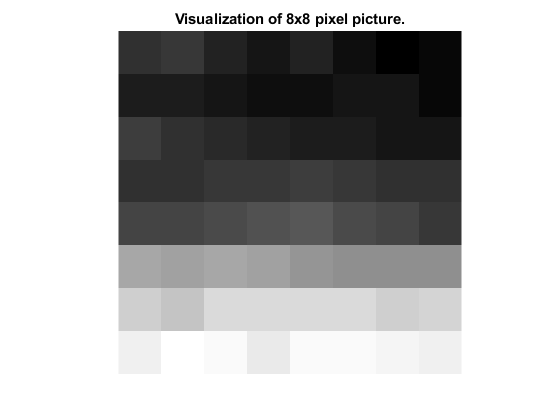

pic_mat =  [124 125 122 120 122 119 117 118
            121 121 120 119 119 120 120 118
            126 124 123 122 121 121 120 120
            124 124 125 125 126 125 124 124
            127 127 128 129 130 128 127 125
            143 142 143 142 140 139 139 139
            150 148 152 152 152 152 150 151
            156 159 158 155 158 158 157 156];

figure()
imshow(log(abs(pic_mat)),[],'InitialMagnification','fit');
title('Visualization of 8x8 pixel picture.')

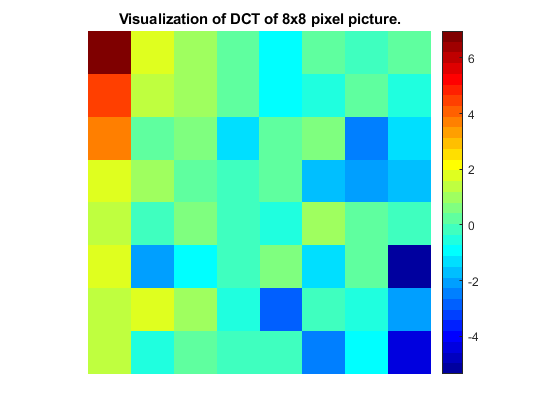

dct_mat = dct2(pic_mat);

figure()
imshow(log(abs(dct_mat)),[],'InitialMagnification','fit');
title('Visualization of DCT of 8x8 pixel picture.')
colormap(gca,jet(32))
colorbar

Here we see that the highest consentration of frequencies in the picutre is in the low frequencies. Elsewhere we have some minor contributions to some of the higher frequency components.

#### b)

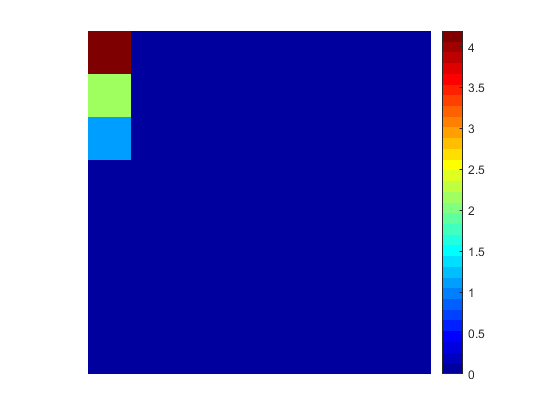

quant_table =  [16 11 10 16  24  40  51  61;
                12 12 14 19  26  58  60  55;
                14 13 16 24  40  57  69  56;
                14 17 22 29  51  87  80  62;
                18 22 37 56  68 109 103  77;
                24 35 55 64  81 104 113  92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103  99];

k = floor((dct_mat./quant_table) + 0.5);

figure()
imshow(log(abs(k)),[],'InitialMagnification','fit');
colormap(gca,jet(32))
colorbar

After doing the quantization most of the semi-high and high frequency components have been zeroed out, while the low frequencies are kept.

By encoding/quantizing the image after having done the dct we are able to filter out most of the irrelevant information in the picture. While if we had quantized the picture first, then done the dct it would first have filtered the image by the quantization table, then piced out the low-high frequencie components of the distorted quantized version of the origianl image. Which would not help in reducing the size of the image by removing irrelevancy, it would just make another distorted version if the original image.

#### c)

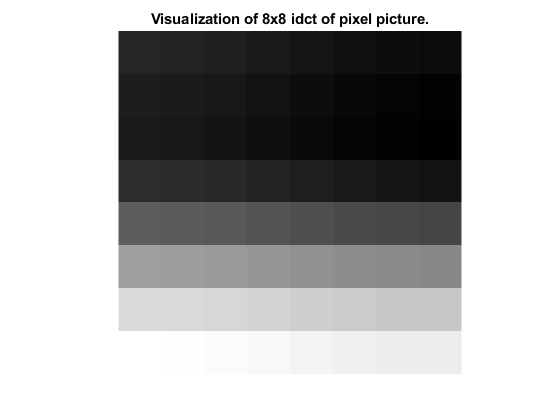

% TODO: ask in help lecture if this is sufficient, or if we have to use
% another formula (same with calculation of PSNR).
dct_mat_inv = ((k).*quant_table);
idct_pic = idct2(dct_mat_inv);

figure()
imshow(log(abs(idct_pic)),[],'InitialMagnification','fit');
title('Visualization of 8x8 idct of pixel picture.')

Based on the following formulas:

$\text{PSNR}_{dB} = 10\cdot \text{log}_{10} \frac{255^2}{\sigma_e^2}$, where $\sigma_e^2 = \frac{1}{MN}\sum_{m=1}^M \sum_{n=1}^N|u(m,n)- \hat u (m,n)|^2$ (from lecture 2, slide 47)

We get the following PSNR:

M = length(pic_mat(:,1));
N = length(pic_mat(1,:));

% Tested if the results were similar with loop and what was done below (it
% was)
% sigma_e2 = 0;
% for m = 1:M
%     for n = 1:N
%         sigma_e2 = sigma_e2 + abs((pic_mat(m,n) - idct_pic(m,n)));
%     end
% end
% sigma_e2 = sigma_e2/(M*N);

sigma_e = (1/(M*N))*sum(abs(pic_mat - idct_pic),'all');
% Not sure if we should use 'abs()' in the above expression, ref. L3-Visual
% compression slide 9.
PSNR = 10*log10((255^2)/(sigma_e^2));
% PSNR2 = 10*log10((255^2)/(sigma_e2^2));
fprintf('PSNR = %f dB\n', PSNR)%, PSNR2)

PSNR = 42.651402 dB


### 2 - Prediction:

#### a)

Given $x(n)
$, with auto-correlation given by $R_x(k) $, with $R_x(0) = \sigma_x, \text{ } R_x(1) = a, \text{ } R_x(k)=0, \text{ for}  \text{ } |k|>1.$

Starting with the Normal Equation we have:


$$\sum_{k=0}^p a_k \gamma_{xx}[n-e] = - \gamma_{xx}[n]
$$


Using p = 2 for second order LP we get:


$$(1) \text{ } a_1 \gamma_{xx}[0] + a_2 \gamma_{xx}[-1] = -\gamma_{xx}[1]$$



$$(2) \text{ } a_1 \gamma_{xx}[1] + a_2 \gamma_{xx}[0] = - \gamma_{xx}[2]$$


From what was given above, and having that $R_x(k) == \gamma_{xx}[k]$, we have:


$$\gamma_{xx}[0] = \sigma_x, \text{ } \gamma_{xx}[1] = \gamma_{xx}[-1] = a \text{ and otherwise } \gamma_{xx}[k] = 0$$
 

Putting these values into the above equations (1) and (2) we get the equation set


$$(1) \text{ } a_1\sigma_x + a_2\cdot a = -a$$



$$(2) \text{ } a_1\cdot a + a_2\sigma_x = 0$$



$$\left[\matrix{ \sigma_x & a \cr a & \sigma_x}\right] = \left[\matrix{ -a\cr0}\right]$$
 
$$\rightarrow
\left[\matrix{ 1 & 0 \cr 0 & 1 }\right] = \left[\matrix{ \frac{a\sigma_x}{\sigma_x^2 - a^2} \cr \frac{a^2}{a^2 - \sigma_x^2}}\right]$$


Hence the coefficients for the optimal linear predictior is:


$$a_0 = 1, \text{ } a_1 = \frac{a\sigma_x}{\sigma_x^2 - a^2} \text{ and } a_2 = \frac{a^2}{a^2 - \sigma_x^2}$$


### 3 - Compression Basics:

#### a)

Lossless compression consists of two main steps. The first is using a wavelet or dct transform for redundancy reduction, and the last one is coding the "image" with a lossless coding shceme.

For lossy compression we first have a similar step to the lossless compression, where redundancy is handeled by a wavelet or dct transform, then following that the image is quantized to remove irrelevancy (this is mainly where the loss is introduced) and lastly the image file is coded with a fitting coding scheme.

#### b)

Partly answered in a) (not for the coding part)

#### c)

#### d)

One can look at the PSNR of the image as we did in 1c, this gives how good the signal strenght in the compressed picture is in relation to the original image.

## Part 2:

### 4 - JPEG and JPEG2000:

#### a)

With the newer JPEG 2000 (J2K) a bunch of new features were introduced into this standard, compared with its predecessor JPEG. 

#### Difference in functionalities:

In J2K there were introduced scalability (where images could be scaled to different formats in a lossless manner from the original image), a more robust error rescilience for broadcasting channels with a high BER, where the PSNR for J2K was slightly higher than for JPEG (ref Table 8, in reading material document 3) for no or low BER, while for higher BER's the difference were more significant. 

J2K also has a functinality for ROI (should possibly be in the next section)

#### Difference in coding techniques:

As J2K uses a wavelet based transform vs JEPG's dct, J2K will not have the same problem with blocking artifacts for lower bit-rate images. 

#### b)

Comparison of images...

#### c)

Describe errors (blocking, conturing (for JPEG), ringing (for JPEG 2000))

#### d)

bike = imread('Program\ Files\bike.pgm');

Error using imread>get_full_filename (line 567)
File "Program\ Files\bike.pgm" does not exist.

Error in imread (line 374)
    fullname = get_full_filename(filename);

cafe = imread('Program\ Files\cafe.pgm');
woman = imread('Program\ Files\woman.pgm');